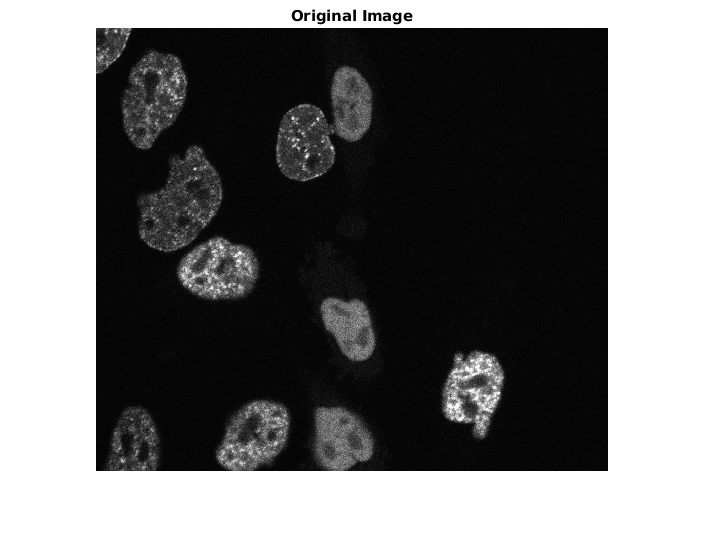

% Implementation of Phase Stretch Transform (PST) in Matlab
% author: M. Asghari and Madhuri Suthar, Jalali Lab, Department of Electrical and Computer Engineering,  UCLA

clc  % clear screen
clear all  % clear all variables
close all   % close all figures

% import original image
filename = 't000.tif';
filepath =strcat('Fluo-N3DH-CHO/01/',filename);
stack_size = length(imfinfo(filepath));
Image_orig=imread(filepath, 1);
Image_orig = im2gray(Image_orig);
% if image is a color image, convert it to grayscale
try
    for i = 2:stack_size
        tiff = imread(filepath, i);
        tiff = im2gray(tiff);
        Image_orig = cat(3, Image_orig, tiff); 
    end
catch
end

% Repeat the Z axis by 5x, since the voxels are not even in X/Y/Z
% Voxel size (microns): 0.202 x 0.202 x 1.0
% Repeating Z axis by 5x should make the voxel size 0.202 x 0.202 x 0.2
% (good enough)
Image_orig = repelem(Image_orig, 1, 1, 5);

%show the original image
%subplot(1,2,1)
%Image_orig = im2double(Image_orig(:,:,:));
imshow(Image_orig(:,:,1))
title('Original Image') % convert the grayscale image do a 2D double array

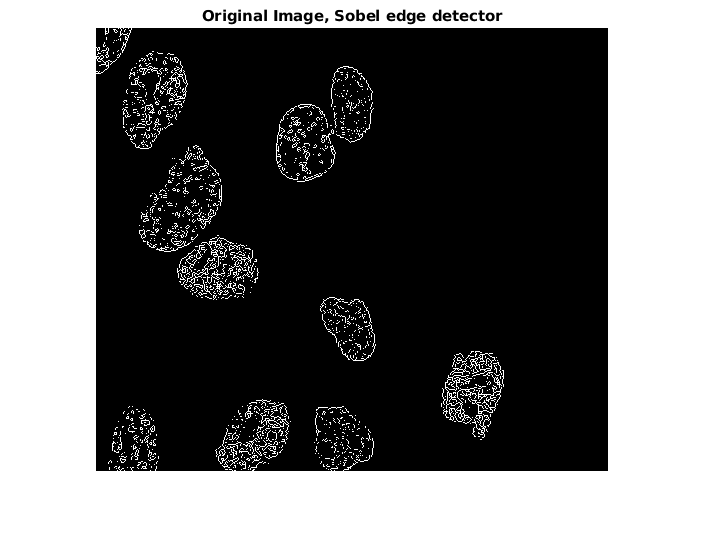

%Image_orig=double(Image_orig);

% MK: Show edges using 1st order Sobel edge detector kernel
figure;
edge(Image_orig(:,:,1), 'sobel');
title('Original Image, Sobel edge detector');

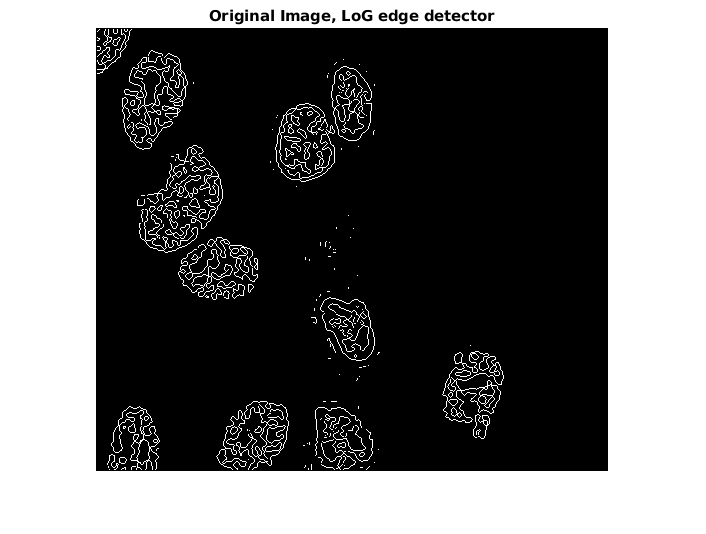

figure;
edge(Image_orig(:,:,1), 'log');
title('Original Image, LoG edge detector');

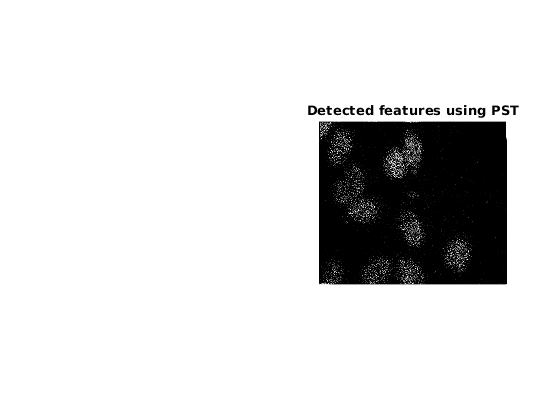

figure;

% low-pass filtering (also called localization) parameter
handles.LPF=0.2; % Gaussian low-pass filter Full Width at Half Maximum (FWHM) (min:0 , max : 1)

% PST parameters
handles.Phase_strength=0.48;  % PST  kernel Phase Strength
handles.Warp_strength=9.9;  % PST Kernel Warp Strength

% Thresholding parameters (for post processing)
handles.Thresh_min=-1;      % minimum Threshold  (a number between 0 and -1)
handles.Thresh_max= 0.001;  % maximum Threshold  (a number between 0 and 1)

% choose to compute the analog or digital edge
Morph_flag = 0; %  Morph_flag=0 to compute analog edge and Morph_flag=1 to compute digital edge.

% Apply PST and find features (sharp transitions)
[Edge, PST_Kernel]= PST(Image_orig,handles,Morph_flag);

%Attempt to find centroids of blobs
cc = bwconncomp(Edge, 26);
stats = regionprops(cc, 'Centroid');
start_cents = [];
for i = 1:size(stats, 1)
    start_cents = [start_cents ; stats(i).Centroid];
end
prev_size = size(start_cents, 1);
true_centroids = centroid_reduction(start_cents, 50);
curr_size = size(true_centroids, 1);
while prev_size ~= curr_size
    true_centroids = centroid_reduction(true_centroids, 110);
    prev_size = curr_size;
    curr_size = size(true_centroids, 1);
end

% MK: Best edges on Z layer 21
Edge = Edge(:,:,21:25);

%TODO: Make Access Edge not just first element

if Morph_flag ==0
    % show the detected features    
    subplot(1,2,2)
    imshow(Edge(:,:,1)/max(max(Edge(:,:,1)))*3)
    title('Detected features using PST')
    % save the image
    file_and_extension=strsplit(filename,'.');
    output_path=char(strcat('Test_Images/',file_and_extension(1),'_edge.tif'));
    imwrite(Edge(:,:,1)/max(max(Edge(:,:,1)))*3,output_path);
else
    subplot(1,2,2)
    imshow(Edge(:,:,1))
    radii = ones(size(true_centroids, 1), 1) * 55;
    viscircles(true_centroids(:,[1,2]), radii);
    title('Detected features using PST')
    % save the image
    file_and_extension=strsplit(filename,'.');
    output_path=char(strcat('Test_Images/',file_and_extension(1),'_edge.tif'));
    imwrite(Edge(:,:,1),output_path);
    % overlay original image with detected features
    overlay = double(imoverlay(Image_orig, Edge(:,:,1)/1000000, [1 0 0]));
    figure
    imshow(overlay/max(max(max(overlay))));
    title('Detected features using PST overlaid with original image')
    % save the image
    output_path=char(strcat('Test_Images/',file_and_extension(1),'_overlay.tif'));
    imwrite(overlay/max(max(max(overlay))),output_path);
end

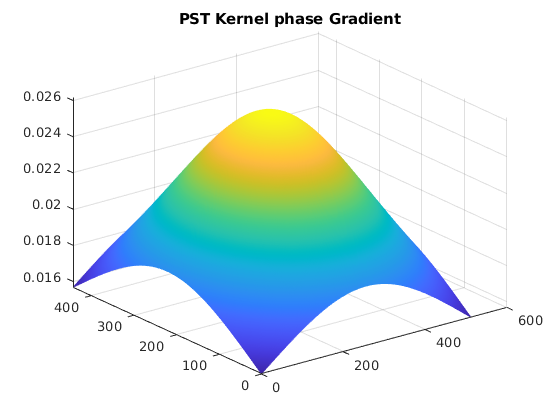


% show the PST phase kernel gradient
figure
[D_PST_Kernel_x D_PST_Kernel_y D_PST_Kernel_z]=gradient(PST_Kernel);
mesh(sqrt(D_PST_Kernel_x(:,:,1).^2+D_PST_Kernel_y(:,:,1).^2+D_PST_Kernel_z(:,:,1).^2));
title('PST Kernel phase Gradient');